# PROYECTO PRIME

Teresa González García y María José Medina Hernández

format compact; clear all; close all;

## 1. Elección de los parámetros de simulación

### Parámetros generales

Fs=250*10^3; % Frecuencia de muestreo
Ts=1/Fs; % Periodo de muestreo

### Parámetros de modulación PSK

m_ary=[2 4 8]; % Número de símbolos de la constelación PSK
m_dpsk=log2(m_ary);

### Parámetros de modulación OFDM

Nc= 96; % Número de portadoras
NFFT=512; % Tamaño FFT
Ncp=48; % Tamaño prefijo ciclico
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % Separacion entre f portadoras

### Parámetros de corrección de errores

R=1/2; %Convolutional coding rate

### Parámetros de aleatorización y desfase

% Secuencia PRBS
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];

### Parámetros de simulación

Para calcular el número de símbolos OFDM por trama, tenemos en cuenta que, como máximo, esta puede durar 100ms ya que es el tiempo máximo en el que se puede considerar el canal estable cuando sea dispersivo. Obtenemos Nofdm = 44.

Tmax=100*10^-3; % Duración máxima de una trama
Nofdm= floor(Tmax/(Tsimb)); % Nofdm

Puesto que se quieren obtener valores de BER fiables inferiores incluso a 10^-4, se necesitan transmitir al menos 10^-4 bits si se quiere obtener esta sensibilidad. Para sensillez del código, se utilizará un número de bits proporcional al número de portadoras, a log2(m-ary) y al número de símbolos OFDM por trama. El mínimo común múltiplo de estos cuatro parámetros es mayor a 10^-4, por lo que es un tamaño válido. En total obtenemos 25344.

Nbits = Nc*lcm(2,3)*Nofdm;

Para calcular el número total de tramas, se divide el número total de bits entre los bits por trama. En total obtenemos 6 para DBPSK, 3 para DQPSK y 2 para DBPSK.

Nbits_trama_DPSK= Nofdm*Nc*m_dpsk;
N_tramas_DPSK=Nbits./Nbits_trama_DPSK;

## 2. Transmisión en un canal ideal

### Transmisión sin aleatorización 

% TODO: poner un flag para que aleatorice o no para demostrar que funciona sin y con aleatorización

% Generación de una secuencia de bits aleatoria
txbits = randi(2,1,Nbits)-1;

% Transmisión con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

% Recepción con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

#### Cálculo del error de transmisión

Cálculo del error de transmisión mediante la comparación de los bits transmitidos con los recibidos

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

### 3. Transmisión en presencia de ruido AWGN

Comparativa BERs teóricas frente a simuladas

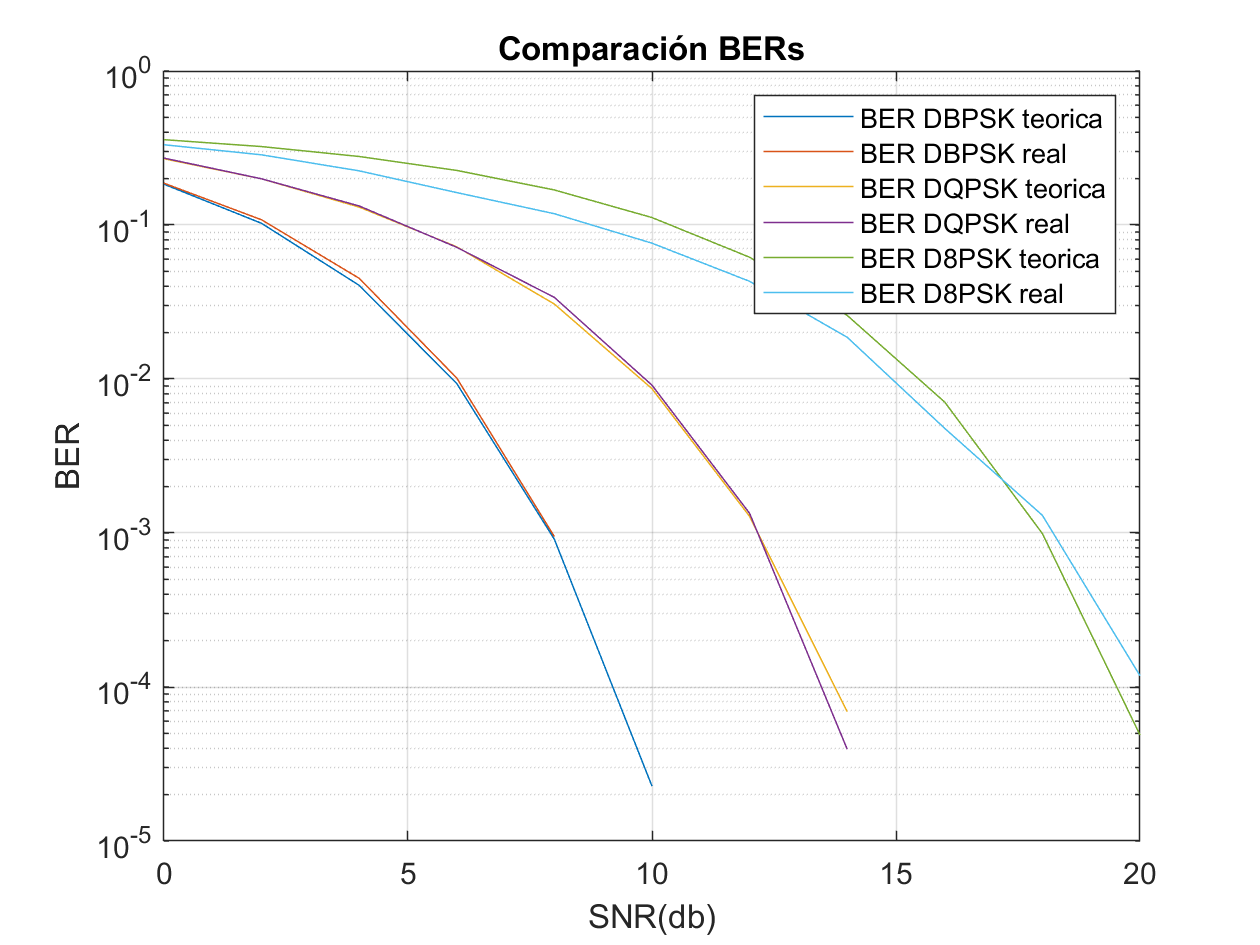

% vector SNR
SNR_db = 0:2:35;

% Cálculo del factor de ancho de banda para distribuir SNR tan solo en la parte
% del espectro con portadoras (Nc)
fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;

% Bucle calculo BER_real_DBPSK
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

% Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

D8PSK + BER CONSTELACION PUNTOS MAS JUNTOS.

        2.   Inclusión de modelo de canal e inclusión de ecualizador

%canal variante en f. Corresponde a un filtro digital de k=9 posiciones en total (en el dominio del tiempo
% discreto):
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1]; % h=[a0...a8]; atenuaciones

   h[n] produce atenuación y retardo por reflexiones dentro de un canal multipath (retardo máximo 8) en la señal a transmitir.

s(t) -> TX

y(t)-> RX

y(t)=conv(s(t),h(t)) -> dominio discreto -> y[n]= conv(s[n],h[n]). 

y[n]=sum(att*s[n-k])- Seguir con esto en latex

H(f) en dbW

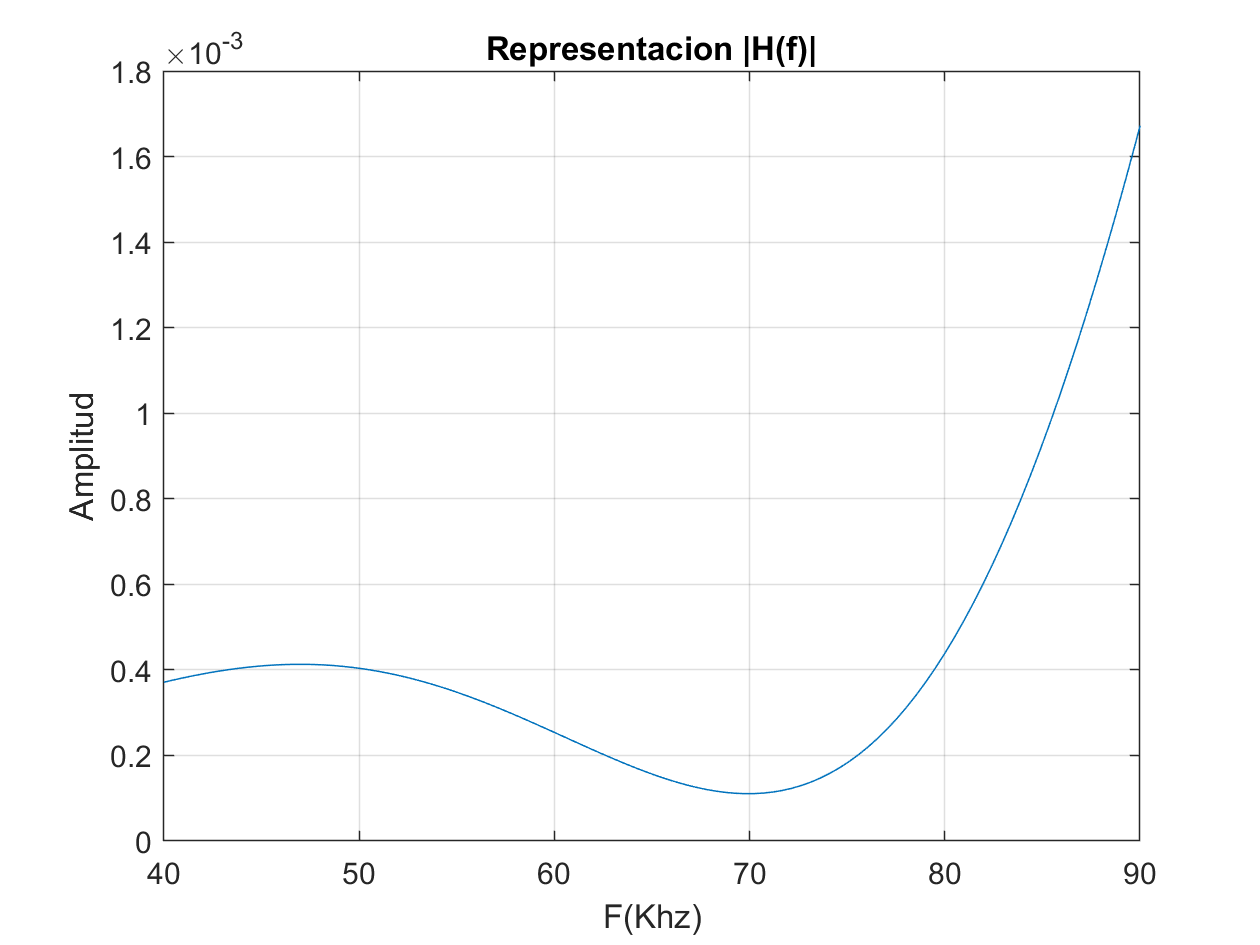

% vector f (paso Fs) -> mitad puntos NFFT espectro + y mitad -. Preguntar

% H(f) es la respuesta al impulso del canal -> FFT.
H=fft(h,NFFT)/NFFT;
f=linspace(-Fs/2,Fs/2, length(H));

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

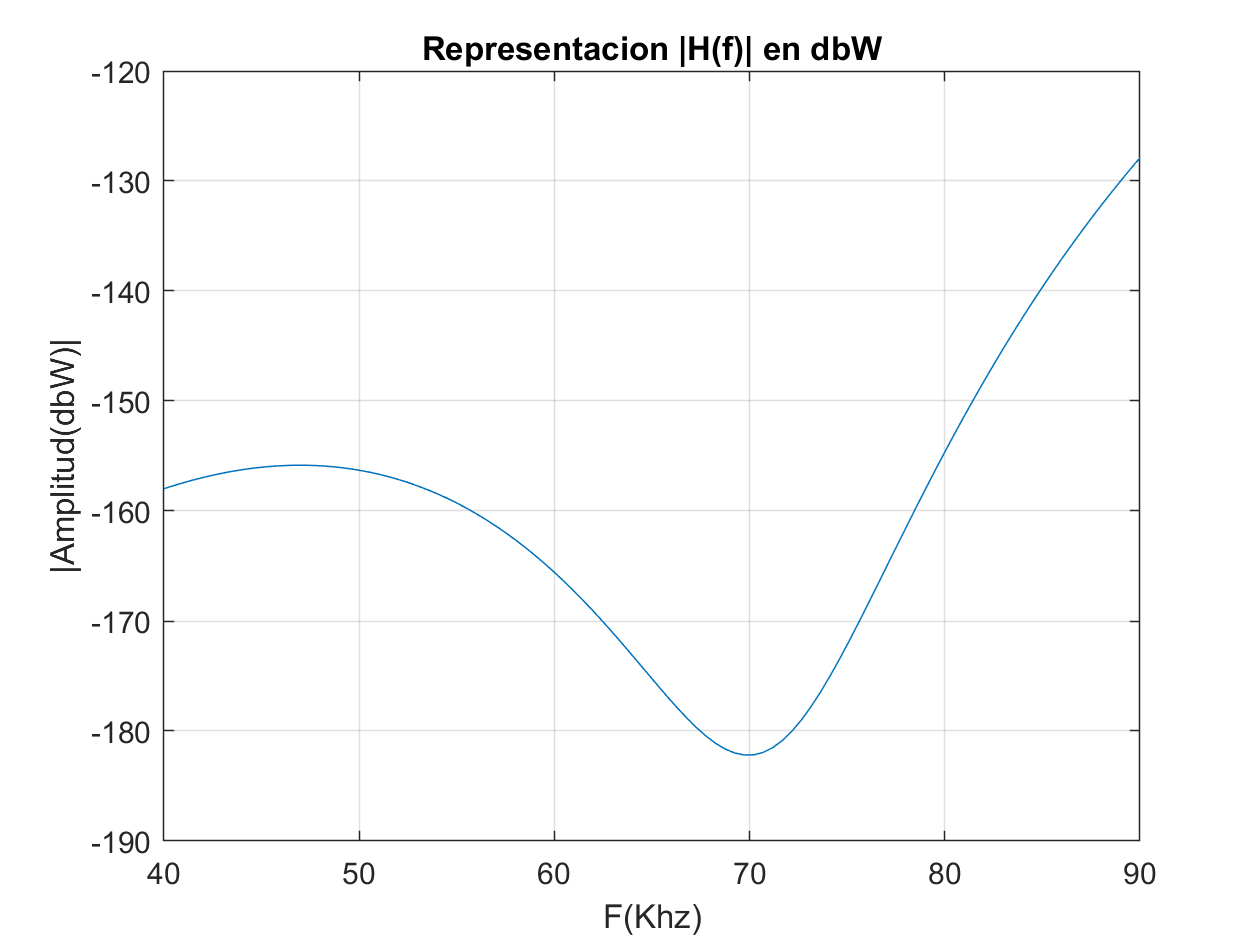

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

## Con canal

Variables globales

global pilotos_dbpsk
global pilotos_dqpsk
global pilotos_d8psk

%convolucion lineal sin cp y añadimos awgn
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1)

y_canal_DBPSK =    -3.4000   10.3168  -14.8705   16.8131  -19.1957    8.3300    2.6490   -2.6100    1.4799    0.5861   -5.1249    2.6138    2.6530   -3.5300    3.5032    0.5801   -7.0745    3.4941    4.2940   -4.0405    2.0057   -0.1886   -5.4325    4.9558    3.1836   -4.9452    0.9917    0.0038   -1.6442    4.4540   -1.6733   -3.7805    4.1844   -0.4835   -2.2176    2.8146   -2.1489   -0.6175    3.8843   -2.9164   -1.2537    3.2124   -2.4929    0.1121    3.4936   -3.4041   -1.5378    3.7689   -0.7673   -1.8902


y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1)

y_canal_DQPSK =     3.2000  -11.8614   21.4895  -27.1657   28.4689  -16.1546   -1.3476    9.4505   -7.3013   -1.4635    9.8433   -7.8387   -0.9924    6.8984   -7.5001    1.5802    6.2558   -5.6522    0.9198    0.2031   -4.2872    7.2841    1.5407   -7.6073    1.0939    1.3062    0.6073    3.9627   -3.1197   -4.1393    1.6469    2.0479    2.1835   -0.8664   -3.0176   -0.4314    0.0053    3.1643    2.2383   -4.5630   -0.9354    1.3832   -0.9385    3.7804    0.0118   -4.4081    1.6815   -1.0586    0.0294    6.2091



y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1)

y_canal_D8PSK =    -1.0971    4.8472   -9.8098   13.5524  -15.6994   12.7819   -4.9167    0.0971    1.7608   -0.9766   -2.5090    2.9265    0.1737   -1.7253    1.6310   -1.0375    0.0072    1.4688   -3.1669    1.1832    3.5335   -2.7938   -0.4671   -0.2987   -1.7764    5.4441   -0.0332   -5.9285    3.0176   -0.3358   -1.7099    6.9778   -3.8194   -6.3891    6.7071   -0.4997   -1.9597    4.9880   -6.0367   -1.7573    8.1269   -4.0716   -2.1237    3.7970   -3.9697    2.9282    2.3958   -7.4087    3.8318    3.8543


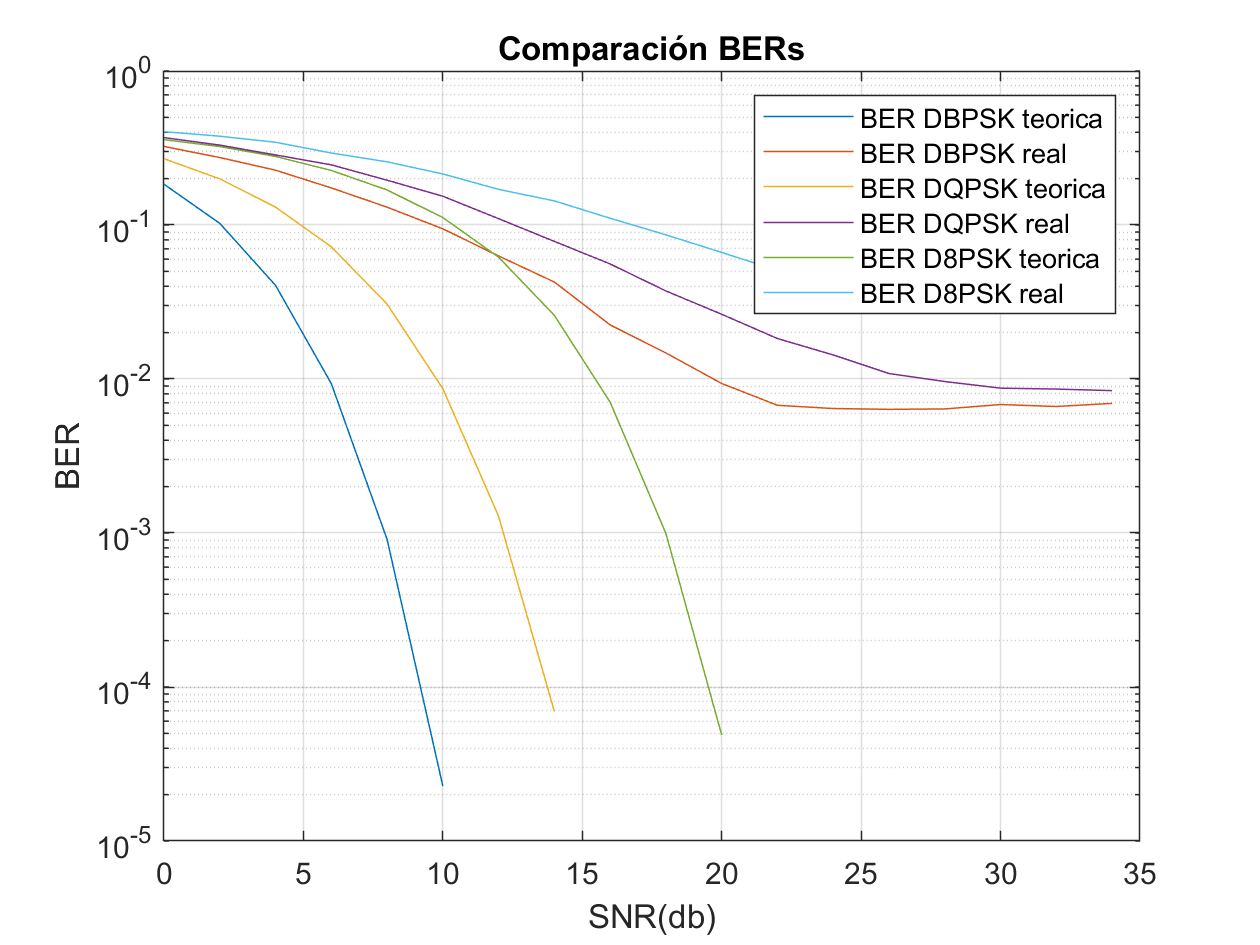

%añadimos el ruido
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

FONDO DE BER EN TORNO 10^-2. eq lo quitara. BPSK MENOR BER

%incluir prefijo ciclico ncp=48. asi se puede recuperar el canal con la
%inversa (problema FFT)
%vectores extendidos
x_tx_DBPSK_cp= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_DQPSK_cp= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_D8PSK_cp= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp);

Suponemos que desconocemos el canal.  Finjimos que conocemos el primer simbolo OFDM que recibes entre el primero que has enviado para estimar el canal

%receptor sin ruido para ver que nos quita bien el prefijo

y_rx_DBPSK_cp=receptor(x_tx_DBPSK_cp, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_DQPSK_cp=receptor(x_tx_DQPSK_cp, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_D8PSK_cp=receptor(x_tx_D8PSK_cp, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);


Comprobacion tras ecualizacion y sin ruido error=0.

error_dbpsk = sum(abs(txbits-y_rx_DBPSK_cp))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-y_rx_DQPSK_cp))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-y_rx_D8PSK_cp))

error_d8psk = 0

Convolucionamos con la extendida

y_canal_DBPSK_cp=conv(x_tx_DBPSK_cp,h);
y_canal_DBPSK_cp =y_canal_DBPSK_cp(1:end-length(h)+1);

y_canal_DQPSK_cp=conv(x_tx_DQPSK_cp,h);
y_canal_DQPSK_cp =y_canal_DQPSK_cp(1:end-length(h)+1);

y_canal_D8PSK_cp=conv(x_tx_D8PSK_cp,h);
y_canal_D8PSK_cp =y_canal_D8PSK_cp(1:end-length(h)+1);

Añadimos ruido para calcular BER

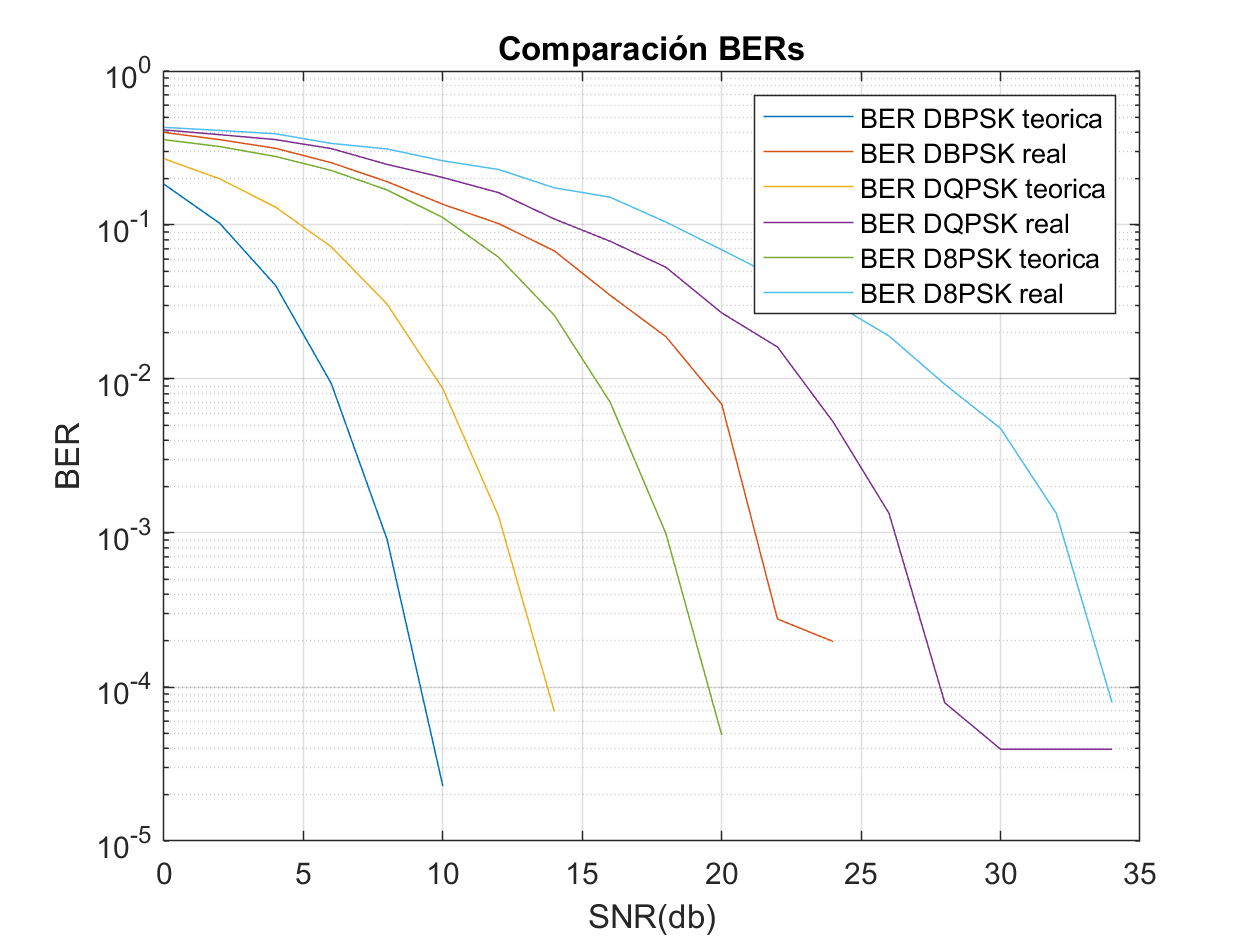

%añadimos el ruido

for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK_cp,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_dqpsk_cp=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_d8psk_cp=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk_cp);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk_cp);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk_cp);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

## FEC